clear;
clf;

% Post proscessing of FreeFem++ data in matlab.
% Claire R.A Curry

% Figure options
figure('Resize','off','ToolBar','none','MenuBar','none')
set(gca,"NextPlot","replacechildren")
xlabel("x")
ylabel("y")
zlabel("u(x,y,t)")

% Code to convert data output by FreeFem++ to matlab readable data
% Using the ffmatlib library
% https://github.com/samplemaker/freefem_matlab_octave_plot
addpath('ffmatlib');
[p,b,t]=ffreadmesh('HPMovie.msh');
vh=ffreaddata('HPMovieVh.txt');

% Initializing video writer object
v = VideoWriter("HPMovie2");
v.Quality = 100;
v.FrameRate = 15;
open(v)

% Reading FreeFem++ output data
totalFrames = 101

totalFrames = 101

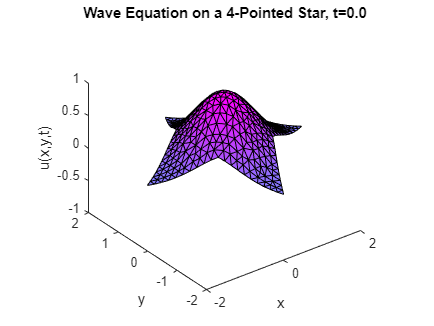

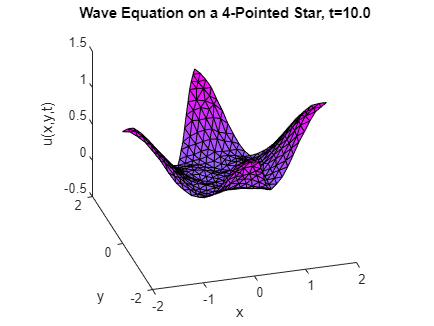

for j = 0:totalFrames-1
    name = sprintf('HPMovie%i.txt', j);
    u(:,j+1) = ffreaddata(name);
end

% Test plot of initial conditions
title("4-Pointed Star with Asymmetric Initial Conditions")
ffpdeplot(p,b,t,'VhSeq',vh,'XYData',u(:,1),'ZStyle','continuous','Mesh','on', ...
    'Contour','off','ColorRange','on','ColorBar','off', 'Xlim', [-2 2], ...
    'Ylim', [-2 2], 'Zlim', [-1 1]);

% Plotting all frames and saving to video writer object
for j = 1:totalFrames
    title(sprintf("Wave Equation on a 4-Pointed Star, t=%0.1f", (j-1)*0.1))
    ffpdeplot(p,b,t,'VhSeq',vh,'XYData',u(:,j),'ZStyle','continuous','Mesh','on', ...
        'Contour','off','ColorRange','on','ColorBar','off', 'Xlim', [-2 2], ...
        'Ylim', [-2 2], 'Zlim', [-0.5 1.5]);
    view([-16.286,27.1402])
    drawnow;
    frame = getframe(gcf);
    writeVideo(v,frame);
end


close(v)
